# Trajectory Generation

## Load the map

load maps/complexmap2.mat;
Resolution=0.1; % meters
map = binaryOccupancyMap(complexMap,Resolution);
uavRadius = .5;

% inflate map
inflate(map,uavRadius);
%save('trajectories/map', 'map');

## Create waypoints

start = [50 25];
waypoint1 = [70 90];
waypoint2 = [200 345];
%waypoint1 = [260 80];
%waypoint1 = [440 190];
%waypoint3 = [330 230];
%waypoint4 = [80 375];
waypoint5 = [120 240];
%waypoint1 = [45 165];
waypoint3 = [100 350];
waypoint4 = [440 380];
%waypoint5 = [450 50];
%waypoint6 = [200 30];
%waypoint6 = [350 150];
% this is where preference happens
% changing priority increases diversity
waypoints = [waypoint1; waypoint2; waypoint3; waypoint4; waypoint5];% waypoint6];% waypoint2; waypoint3; waypoint4; waypoint5; waypoint6];

## Visualize map and waypoints

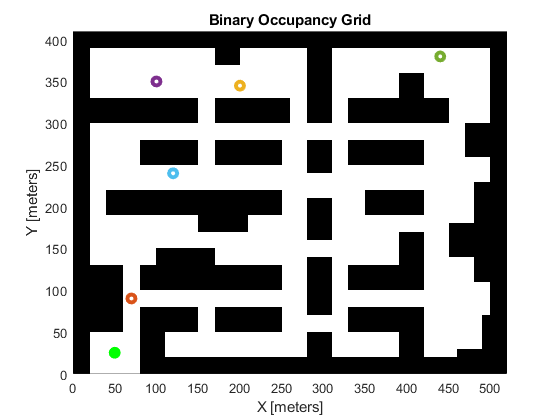

f1 = figure(1); clf;
hold on;
show(map);
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
hold off;

## Build PRM

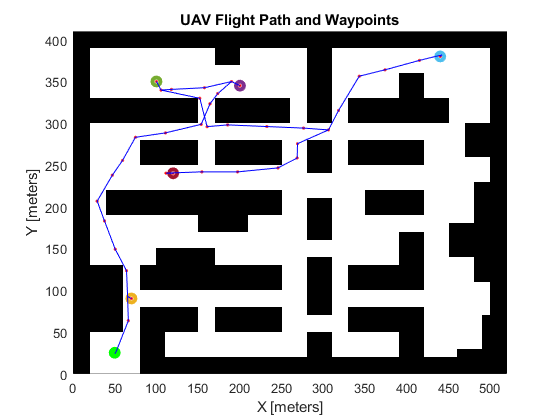

prm = mobileRobotPRM;
prm.Map = map;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

path = findpath(prm, start, waypoint1);
for i = 2:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(map);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

desiredVelocity=1.3; % m/s
path_distance = calculatedistance(path); % total distance to be covered
time_interval = calculatetime(path_distance,desiredVelocity); 
stoptimetotal = time_interval(2)+0.25*time_interval(2); % time to complete the mission
% generate smooth time stamped trajectory
sampletimetraj=1; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:time_interval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);
x_ref_points = [tSamples',q(1,:)'];
y_ref_points = [tSamples',q(2,:)'];
% path_points.x_ref_points = x_ref_points;
% path_points.y_ref_oints = y_ref_points;
% path = [q(1,:) ;q(2,:)]';

load_db_params;
conn = database(datasource_name, user_name, password);

x_points = convert_for_insert(round(x_ref_points(:,2), 2))

x_points = "{50.68, 51.33, 51.97, 52.58, 53.18, 53.76, 54.33, 54.88, 55.42, 55.95, 56.47, 56.98, 57.49, 57.99, 58.48, 58.97, 59.46, 59.95, 60.44, 60.93, 61.42, 61.92, 62.42, 62.91, 63.40, 63.89, 64.37, 64.84, 65.30, 65.75, 66.19, 66.61, 67.02, 67.41, 67.78, 68.13, 68.45, 68.75, 69.02, 69.27, 69.49, 69.68, 69.84, 69.98, 70.10, 70.19, 70.27, 70.33, 70.37, 70.39, 70.41, 70.41, 70.40, 70.38, 70.36, 70.33, 70.30, 70.27, 70.23, 70.20, 70.17, 70.15, 70.12, 70.11, 70.09, 70.07, 70.06, 70.06, 70.05, 70.05, 70.05, 70.06, 70.07, 70.08, 70.09, 70.11, 70.13, 70.15, 70.18, 70.21, 70.24, 70.27, 70.31, 70.34, 70.38, 70.41, 70.44, 70.46, 70.49, 70.50, 70.51, 70.51, 70.50, 70.49, 70.46, 70.42, 70.37, 70.30, 70.22, 70.12, 70.01, 69.89, 69.74, 69.58, 69.41, 69.22, 69.01, 68.80, 68.56, 68.32, 68.06, 67.79, 67.50, 67.20, 66.89, 66.57, 66.24, 65.89, 65.54, 65.17, 64.79, 64.40, 64.01, 63.60, 63.18, 62.75, 62.31, 61.86, 61.41, 60.94, 60.46, 59.98, 59.48, 58.98, 58.46, 57.94, 57.41, 56.87, 56.32, 55.76, 55.20, 

## Write trajectory data to db

write_trajectory_data;

qer = "insert into trajectory_tb (path_distance, path_time, x_waypoints, y_waypoints, x_ref_points, y_ref_points) values (1382.97, 17.73, '{70.00, 200.00, 100.00, 440.00, 120.00}', '{90.00, 345.00, 350.00, 380.00, 240.00}', '{50.17, 50.43, 50.76, 51.18, 51.65, 52.19, 52.77, 53.40, 54.07, 54.77, 55.49, 56.23, 56.97, 57.72, 58.46, 59.18, 59.89, 60.57, 61.21, 61.81, 62.36, 62.86, 63.31, 63.71, 64.06, 64.37, 64.65, 64.89, 65.09, 65.27, 65.42, 65.55, 65.66, 65.76, 65.84, 65.91, 65.98, 66.04, 66.11, 66.18, 66.25, 66.34, 66.44, 66.55, 66.67, 66.80, 66.93, 67.08, 67.22, 67.38, 67.54, 67.69, 67.85, 68.01, 68.17, 68.33, 68.49, 68.64, 68.78, 68.92, 69.05, 69.17, 69.28, 69.38, 69.47, 69.55, 69.62, 69.68, 69.72, 69.76, 69.79, 69.80, 69.81, 69.80, 69.79, 69.76, 69.72, 69.68, 69.62, 69.55, 69.47, 69.38, 69.28, 69.17, 69.05, 68.92, 68.78, 68.63, 68.48, 68.32, 68.16, 67.99, 67.82, 67.65, 67.48, 67.30, 67.13, 66.96, 66.79, 66.62, 66.46, 66.30, 66.15, 66.00, 65.86, 65.73, 65.60, 65.48, 65.36, 65.23, 65.1

## Load trajectory data


%trajectory_tb = sqlread(conn, 'trajectory_tb');
trajectory_tb = readtable('trajectories.csv');
max_flight_time = 22.0;

trajectory_tb = trajectory_tb(trajectory_tb.path_time < max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend');
% randomly select one of the top 3 missions, or the first
if height(trajectory_tb) > 3
    idx = randi(3,1);
else
    idx = 1;
end
trajectory = table2struct(trajectory_tb(4,:));
trajectory.x_waypoints = str2double(regexp(trajectory.x_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.y_waypoints = str2double(regexp(trajectory.y_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.x_ref_points = str2double(regexp(trajectory.x_ref_points,'[+-]?\d+\.?\d*','match'))';
trajectory.y_ref_points = str2double(regexp(trajectory.y_ref_points,'[+-]?\d+\.?\d*','match'))';
times = [1:1:length(trajectory.x_ref_points)]';
trajectory.x_ref_points = [times trajectory.x_ref_points];
trajectory.y_ref_points = [times trajectory.y_ref_points];
clear('trajectory_tb', 'times', 'idx');

rul_hat = 18;
trajectory = get_trajectory('trajectories.csv', rul_hat)

trajectory = struct with fields:
               id: 3
    path_distance: 1.3906e+03
        path_time: 17.8300
      risk_factor: 0.0100
      x_waypoints: '[30.0, 100.0, 410.0, 200.0]'
      y_waypoints: '[150.0, 350.0, 380.0, 30.0]'
     x_ref_points: '[51.07, 52.08, 53.04, 53.94, 54.79, 55.59, 56.35, 57.05, 57.71, 58.32, 58.88, 59.4, 59.88, 60.32, 60.71, 61.07, 61.39, 61.67, 61.92, 62.13, 62.31, 62.46, 62.57, 62.66, 62.73, 62.78, 62.8, 62.81, 62.8, 62.79, 62.76, 62.73, 62.69, 62.65, 62.62, 62.58, 62.56, 62.54, 62.53, 62.53, 62.56, 62.59, 62.65, 62.72, 62.8, 62.9, 63.0, 63.1, 63.21, 63.32, 63.42, 63.52, 63.61, 63.7, 63.77, 63.83, 63.87, 63.89, 63.89, 63.86, 63.81, 63.73, 63.62, 63.48, 63.31, 63.09, 62.85, 62.56, 62.23, 61.86, 61.45, 60.99, 60.49, 59.93, 59.33, 58.68, 57.97, 57.21, 56.4, 55.53, 54.59, 53.6, 52.55, 51.44, 50.28, 49.07, 47.84, 46.58, 45.3, 44.01, 42.72, 41.43, 40.16, 38.91, 37.69, 36.51, 35.37, 34.28, 33.25, 32.29, 31.41, 30.61, 29.9, 29.29, 28.77, 28.34, 27.98, 27.7, 2

trajectory = struct with fields:
               id: 3
    path_distance: 1.3906e+03
        path_time: 17.8300
      risk_factor: 0.0100
     x_ref_points: [1069×2 double]
     y_ref_points: [1069×2 double]
      sample_time: 1
           reward: 1
        waypoints: [4×2 double]
